% Task 1
% Use inverse sampling method to build own function to generate random
% samples from some standard distributions

% Generate n random samples with exprnd
n = 100

n = 100

mu = 2

mu = 2

x = exprnd(mu,1,n)

x =     0.1031    9.1388    3.5696    0.5614    0.3635    1.0022    1.3159    0.1177    0.5990    0.7103    0.5895    0.2697    0.0731    0.0365    0.1697    2.5212    5.6732    0.3945    3.4349    6.7087    0.5193    1.2304    2.2080    1.0956    0.3145    0.8852    1.7345    1.2106    3.4042    2.8855    3.1655    2.6966    0.1182    0.8877    0.3749    1.8896    3.5627    0.6019    0.2721    2.0683    3.4427    0.0072    0.0835    3.7158    0.1474    1.7133    3.0004    3.9844    2.6928    1.2159


% Generate n random values between 0-1
% Calculate inverse exp

u = rand(100,1)

u =     0.9477
    0.0324
    0.9062
    0.3685
    0.6625
    0.9536
    0.0941
    0.6853
    0.4124
    0.1118



% Get inverse
u_inverse = log(1-u)/(-mu)

u_inverse =     1.4752
    0.0165
    1.1830
    0.2298
    0.5432
    1.5355
    0.0494
    0.5781
    0.2659
    0.0593


u_inverse = sort(u_inverse)

u_inverse =     0.0050
    0.0060
    0.0165
    0.0250
    0.0347
    0.0364
    0.0374
    0.0494
    0.0494
    0.0506


% Use Q-Q Plot to check method
% Make theoretical distribuiton
PD = makedist("Exponential",2)

PD =   ExponentialDistribution

  Exponential distribution
    mu = 2


qq = qqplot(u_inverse,PD)

qq =   3×1 Line array:

  Line    (Data)
  Line    (Reference Mid)
  Line    (Reference Ends)


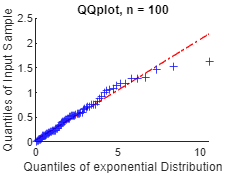

title("QQplot, n = 100")

u = rand(1000,1)

u =     0.8028
    0.8031
    0.8766
    0.0875
    0.6679
    0.5024
    0.3356
    0.5886
    0.3519
    0.2067



% Get inverse
u_inverse = log(1-u)/(-mu)

u_inverse =     0.8119
    0.8126
    1.0463
    0.0458
    0.5512
    0.3490
    0.2044
    0.4440
    0.2169
    0.1158



u_inverse = sort(u_inverse)

u_inverse =     0.0001
    0.0005
    0.0021
    0.0023
    0.0039
    0.0045
    0.0054
    0.0055
    0.0056
    0.0060



qq = qqplot(u_inverse,PD)

qq =   3×1 Line array:

  Line    (Data)
  Line    (Reference Mid)
  Line    (Reference Ends)


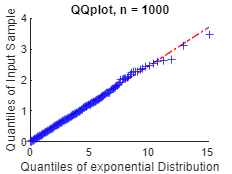

title("QQplot, n = 1000")

u = rand(10000,1)

u =     0.3140
    0.5766
    0.1217
    0.6683
    0.1806
    0.1780
    0.8102
    0.0575
    0.5833
    0.7042



% Get inverse
u_inverse = log(1-u)/(-mu)

u_inverse =     0.1884
    0.4297
    0.0649
    0.5518
    0.0996
    0.0980
    0.8309
    0.0296
    0.4376
    0.6090



u_inverse = sort(u_inverse)

u_inverse =     0.0000
    0.0001
    0.0002
    0.0002
    0.0003
    0.0003
    0.0003
    0.0003
    0.0003
    0.0003



qq = qqplot(u_inverse,PD)

qq =   3×1 Line array:

  Line    (Data)
  Line    (Reference Mid)
  Line    (Reference Ends)


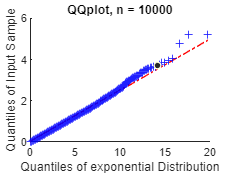

title("QQplot, n = 10000")

% Increasing sample size makes everyhting align better

% Do the above for poisson Distributions

u = rand(1000,1)

u =     0.3399
    0.6587
    0.3718
    0.7497
    0.7385
    0.3325
    0.7678
    0.2687
    0.1937
    0.0396


u_inv = sort(poissinv(u,5))

u_inv =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1



PD = makedist("Poisson",lambda=5)

PD =   PoissonDistribution

  Poisson distribution
    lambda = 5



qq = qqplot(u_inv,PD)

qq =   3×1 Line array:

  Line    (Data)
  Line    (Reference Mid)
  Line    (Reference Ends)


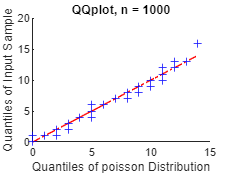


title("QQplot, n = 1000")

% Task 2: Box Muller Method
% Generate normally distributed random variables


u1 = rand(1000,1)

u1 =     0.2135
    0.9798
    0.7323
    0.4718
    0.6532
    0.2234
    0.9592
    0.2569
    0.9942
    0.8433


u2 = rand(1000,1)

u2 =     0.5060
    0.5492
    0.7397
    0.9358
    0.0062
    0.1615
    0.9169
    0.0836
    0.3540
    0.2757



z = sqrt(-2*log(u1)).* cos(2*pi.*u2)

z =    -1.7560
   -0.1925
   -0.0509
    1.1273
    0.9223
    0.9137
    0.2503
    1.4265
   -0.0654
   -0.0940


% z is a sample from N~(0,1)

mean = 10

mean = 10

std = 5

std = 5


z_modified = z* std + mean

z_modified =     1.2199
    9.0376
    9.7457
   15.6363
   14.6113
   14.5683
   11.2513
   17.1326
    9.6730
    9.5298


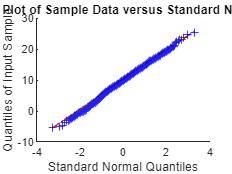

PD = makedist("Normal")
qqplot(z_modified)